## 1. Image Loading

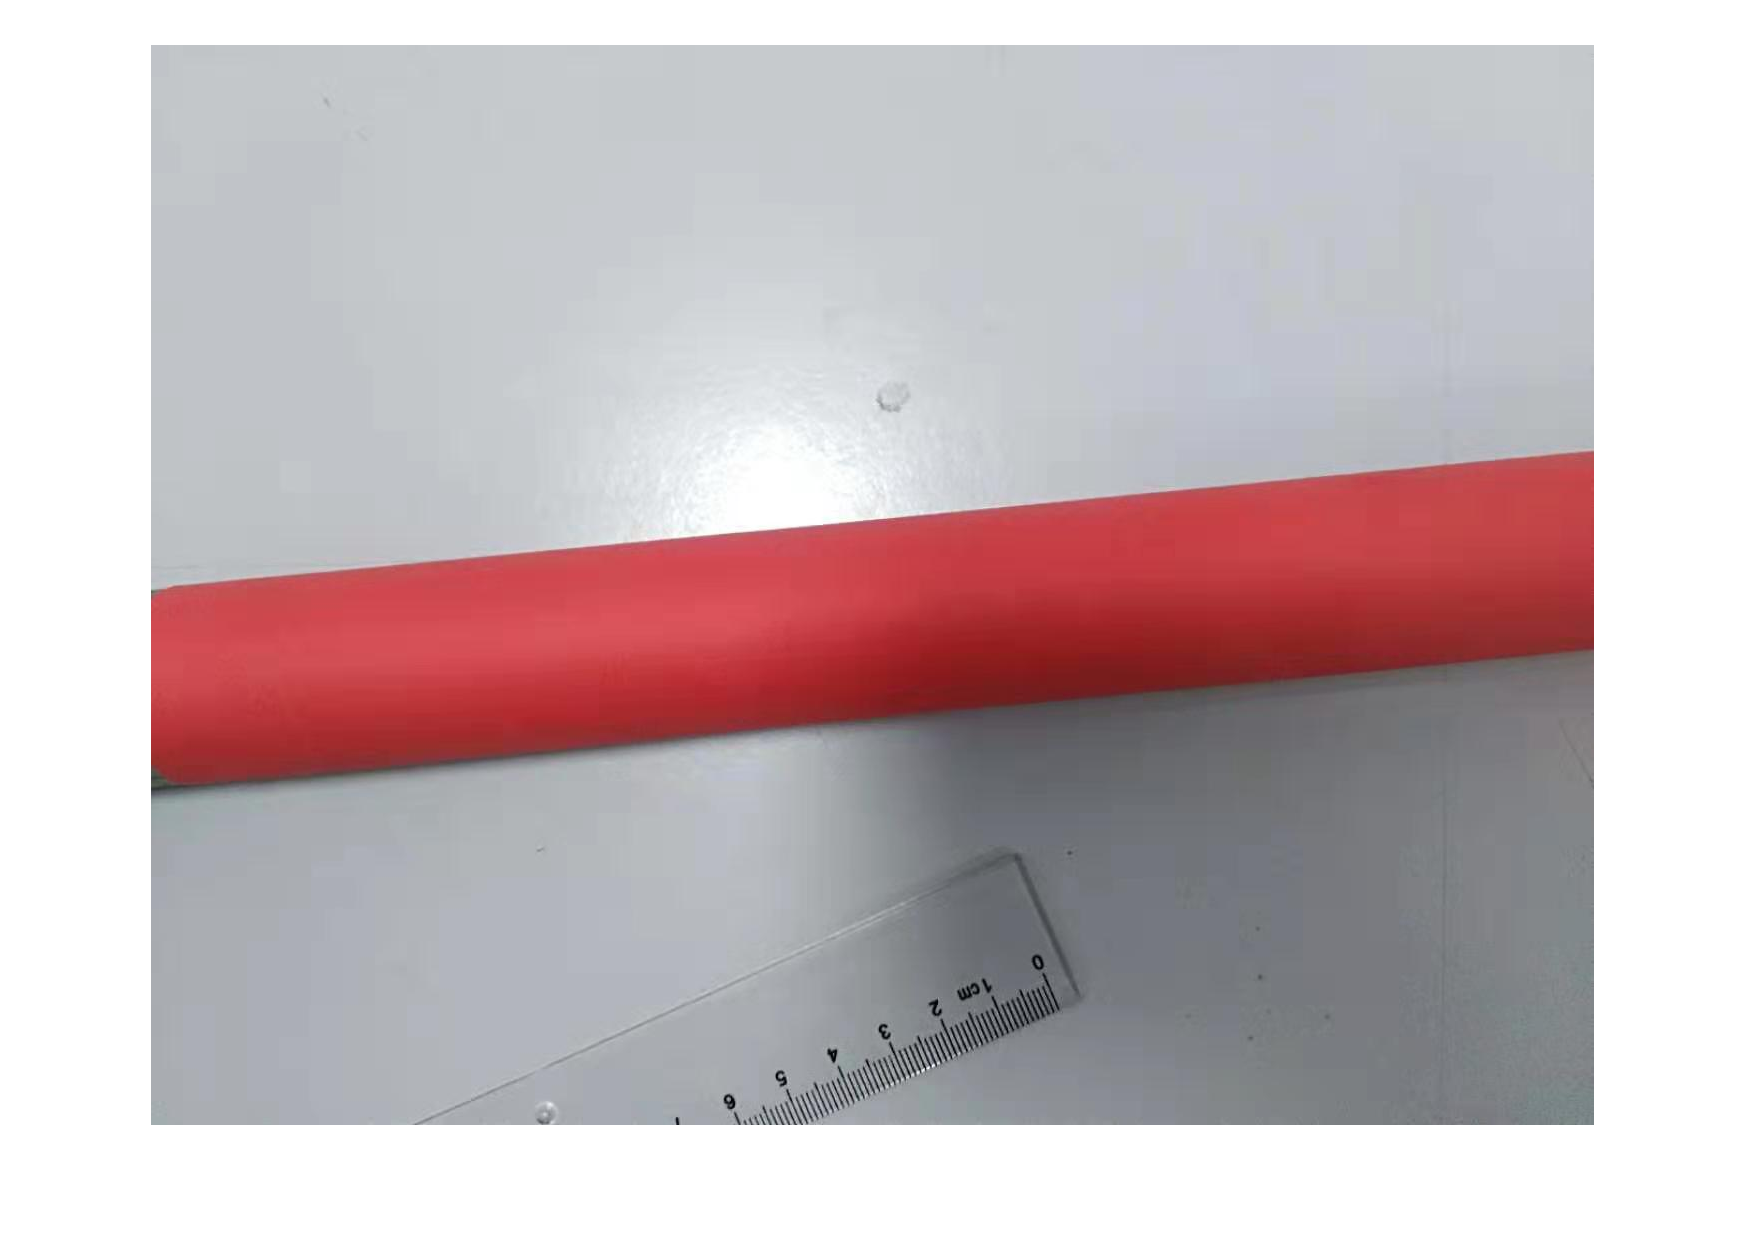

img = imread("./data/3.jpg");
img = im2double(img);
width=size(img,2);
height=size(img,1);

figure, imshow(img);

## 2. Hough Transform

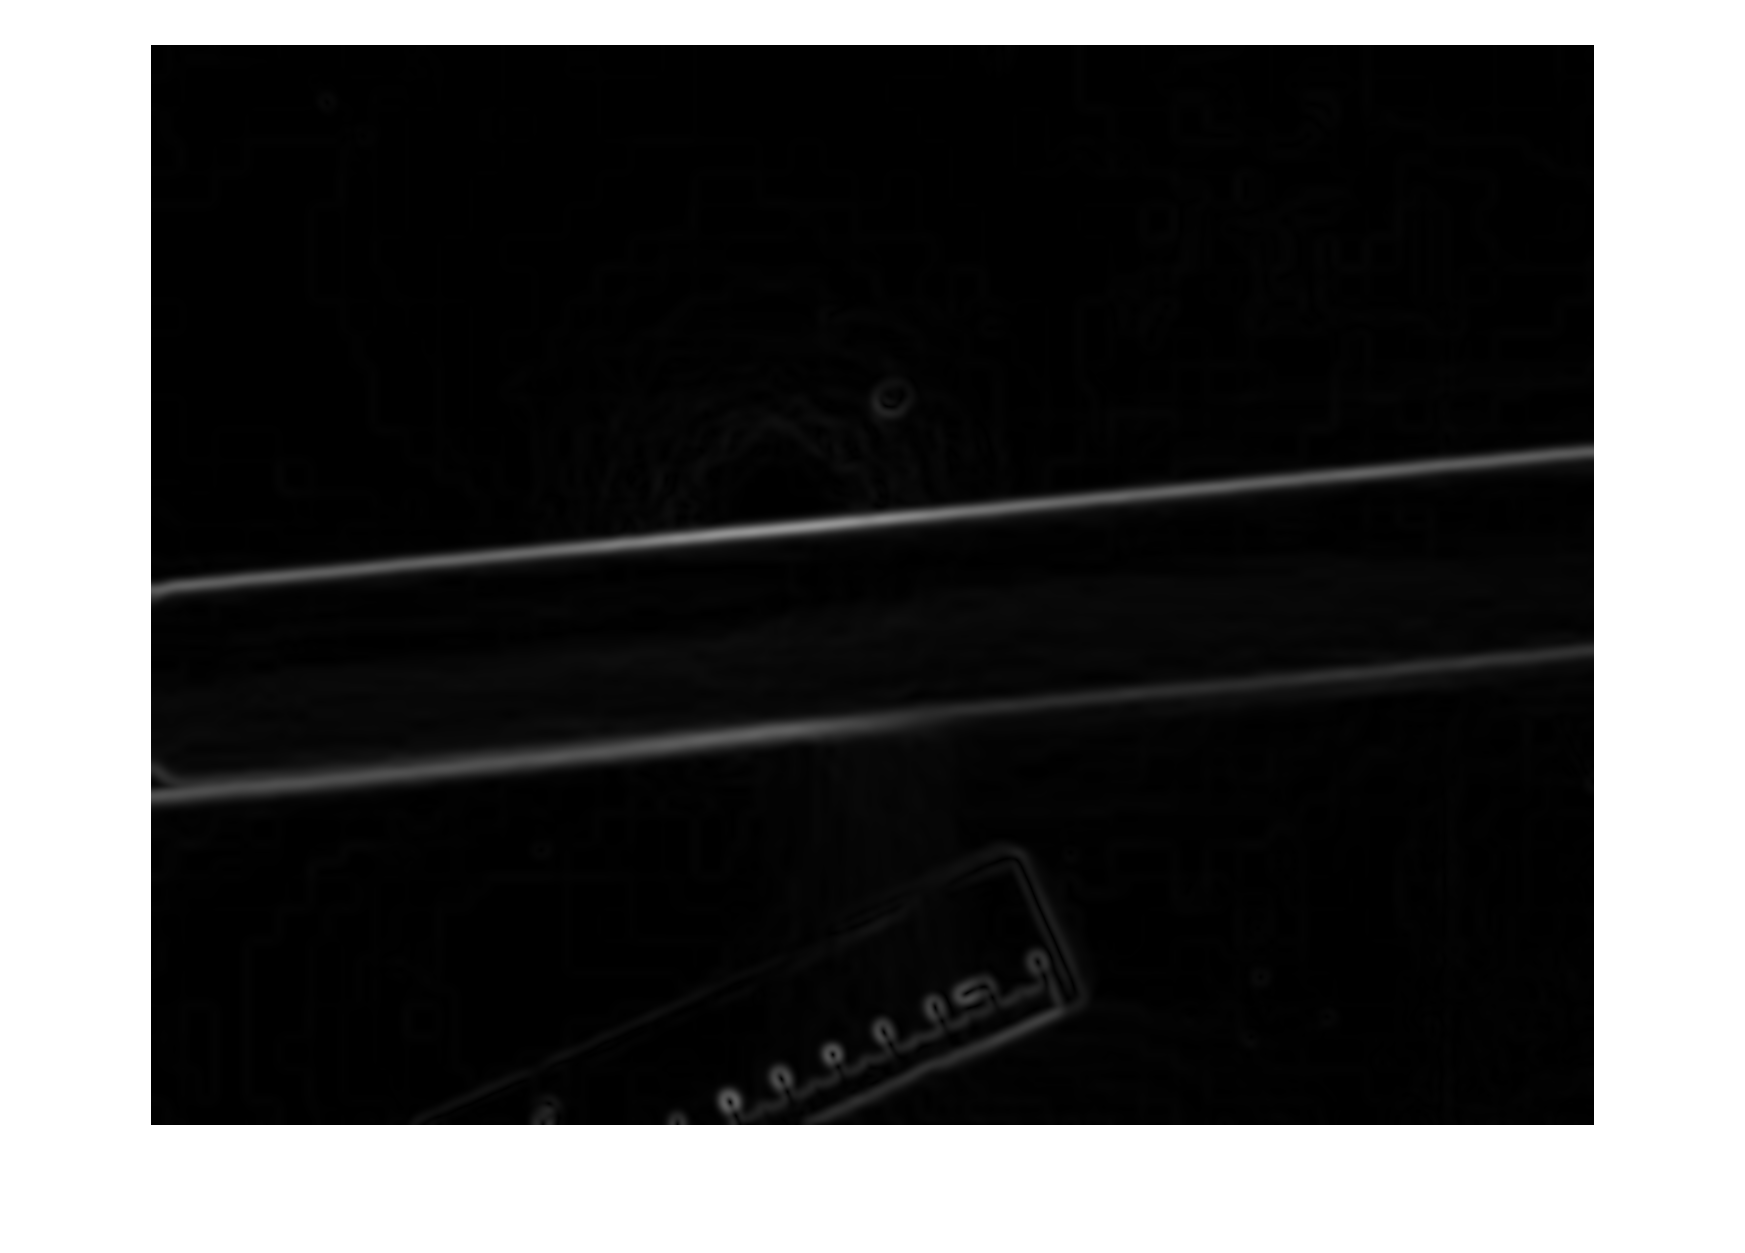

edges = compute_edges(img,5);

figure, imshow(edges);

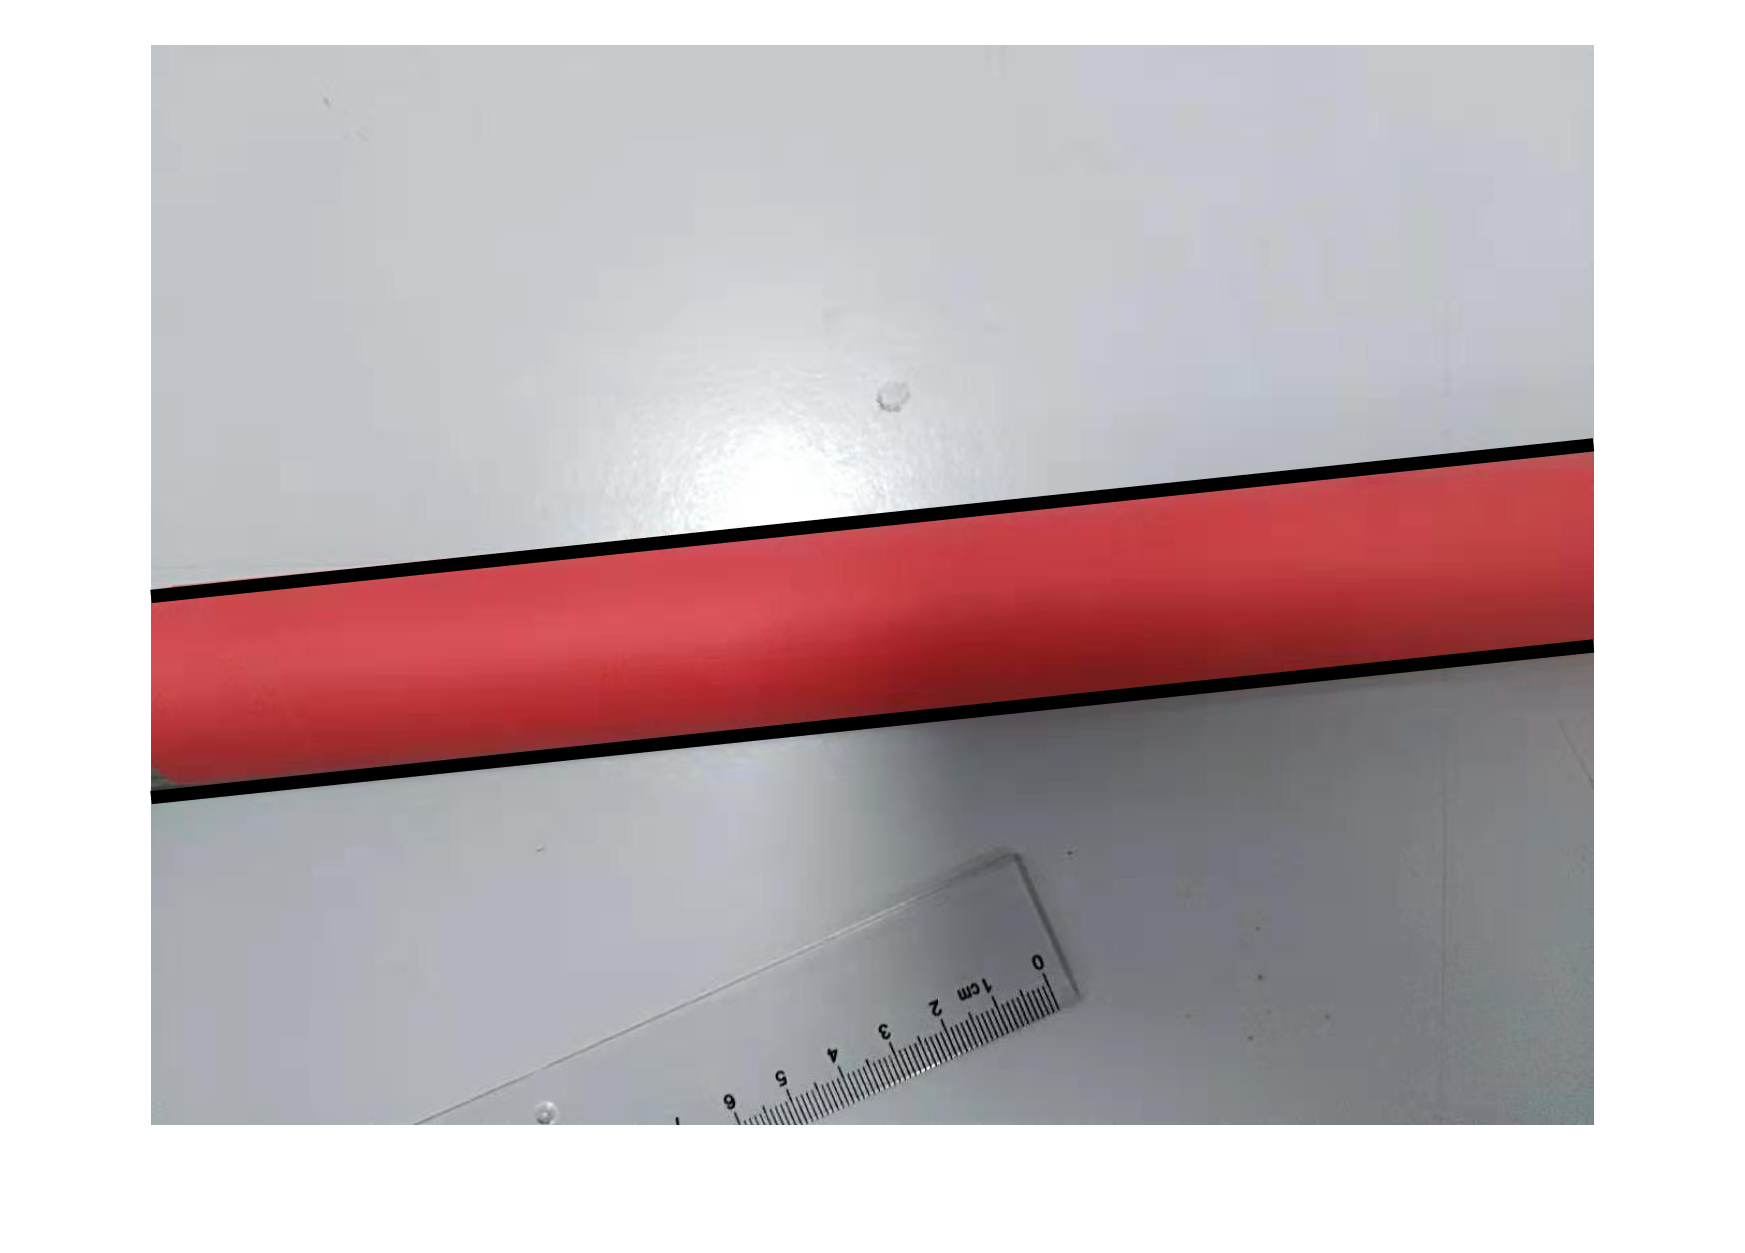

[theta1, rho1, theta2, rho2] = find_parallel(edges,0.03);

figure; imshow(img), hold on
plot_line(width,height,theta1,rho1);
plot_line(width,height,theta2,rho2);

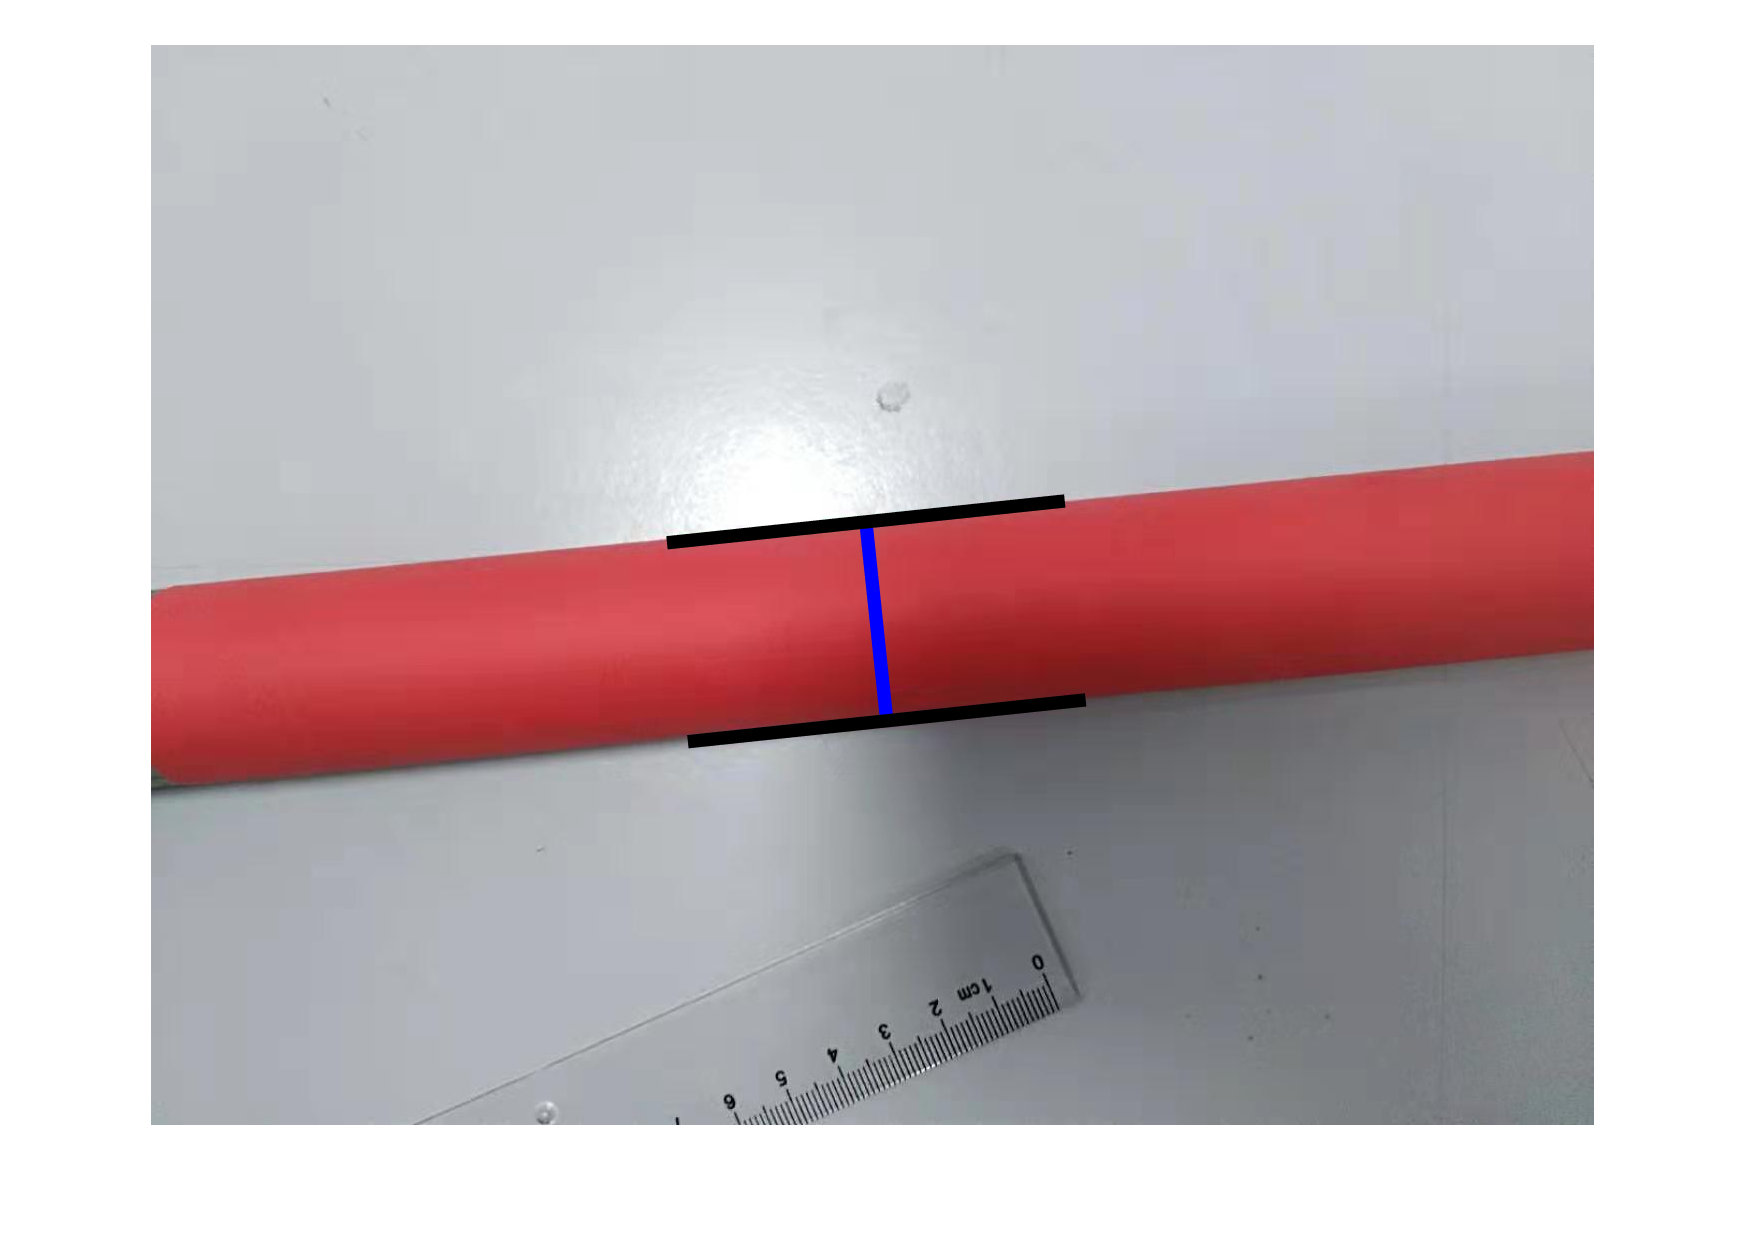

[p1, p2] = initial_points(theta1,rho1,theta2,rho2,width,height);

figure, imshow(img), hold on
plot_ruler(p1,p2);

## 3. Gradient Decent

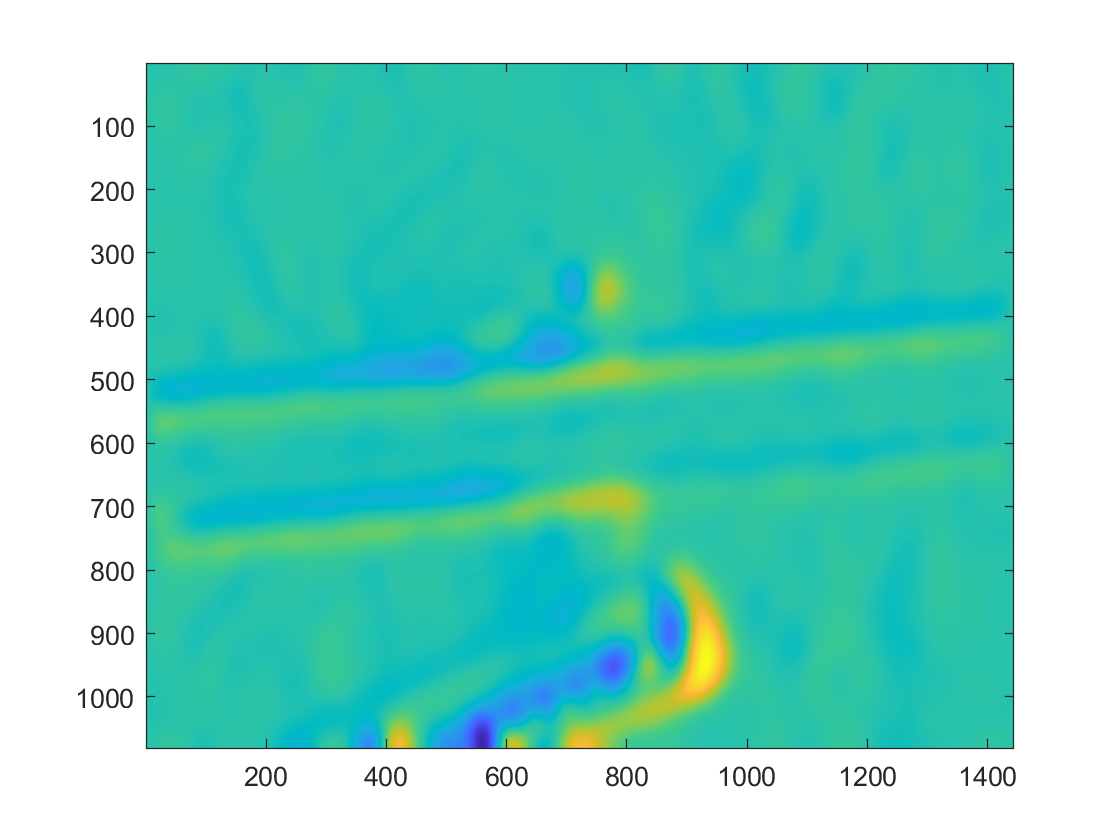

grad = compute_grad(edges,25);

figure, imagesc(grad(:,:,1));

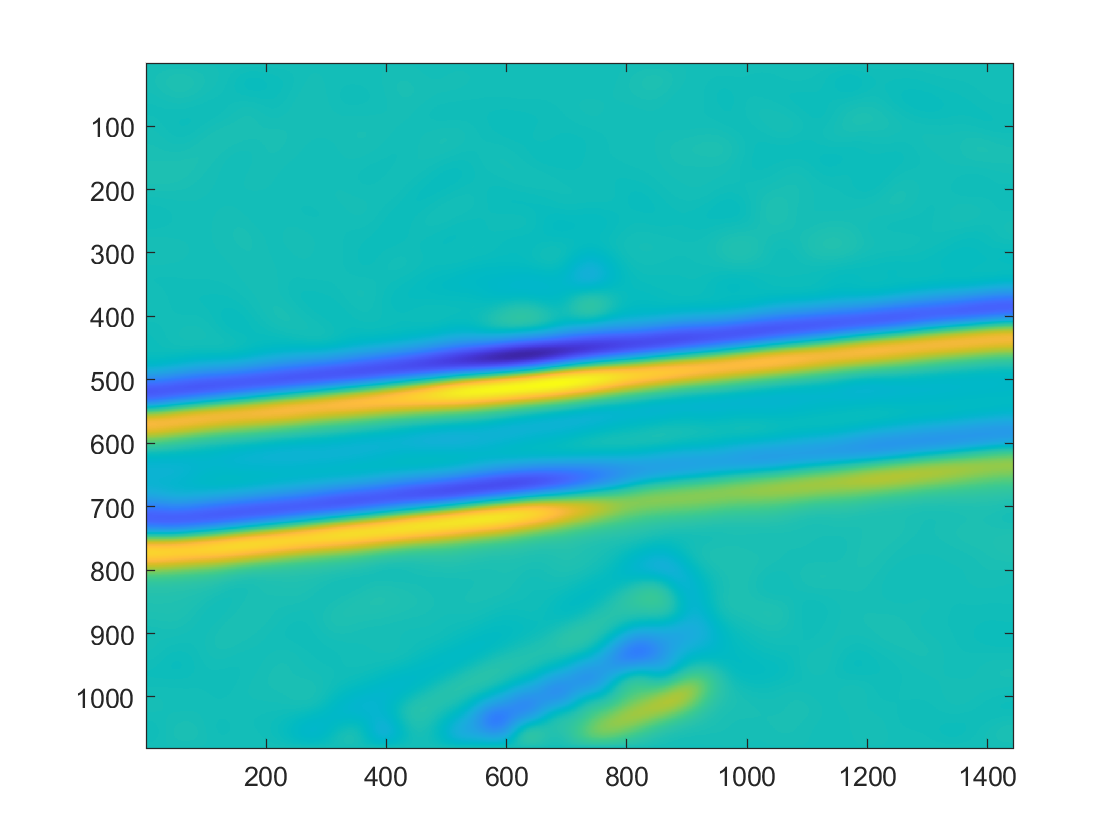

figure, imagesc(grad(:,:,2));

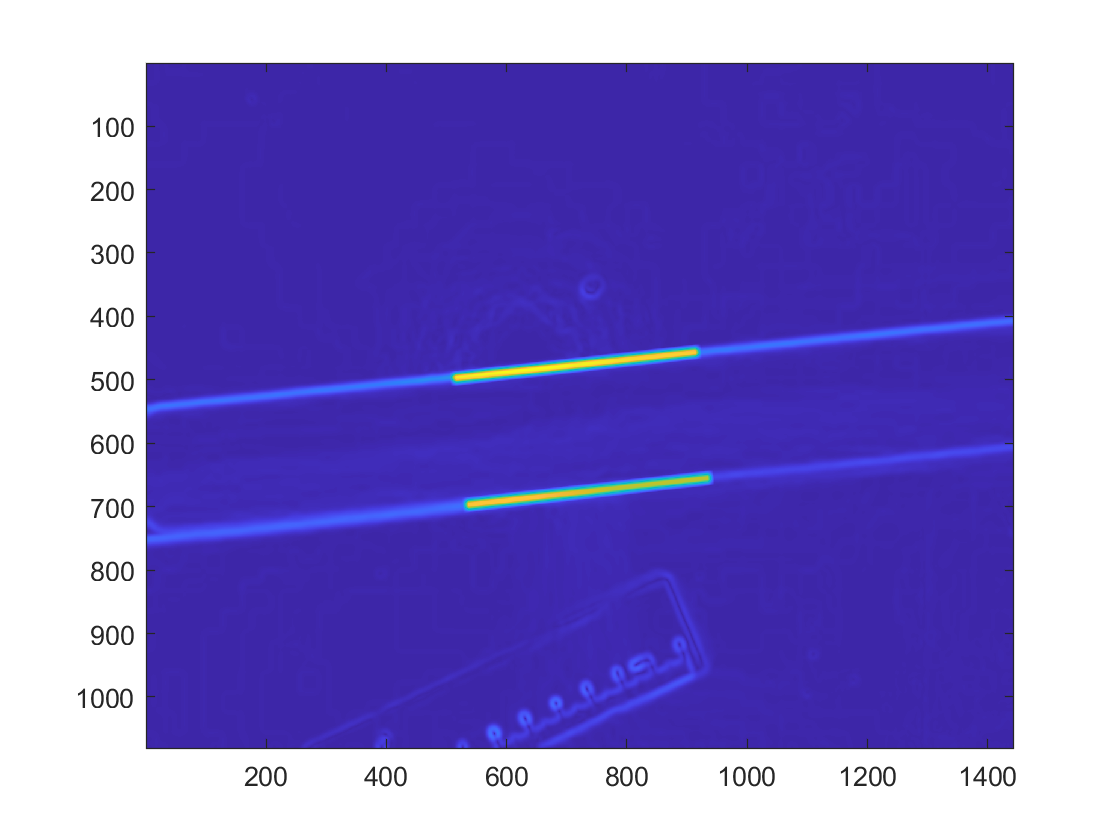

[pxs, pys] = meshgrid(1:width,1:height);
ps = zeros(0,0,0);
ps(:,:,1) = pxs;
ps(:,:,2) = pys;

[line1, line2] = lines_mask(p1,p2,ps,5,10);

figure, imagesc(line1+line2+edges), hold on